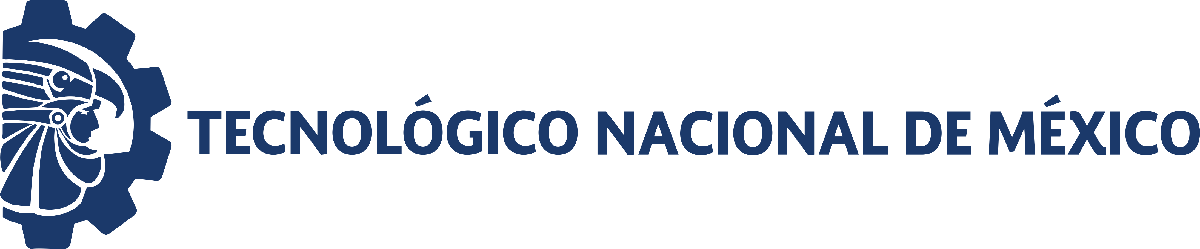                                 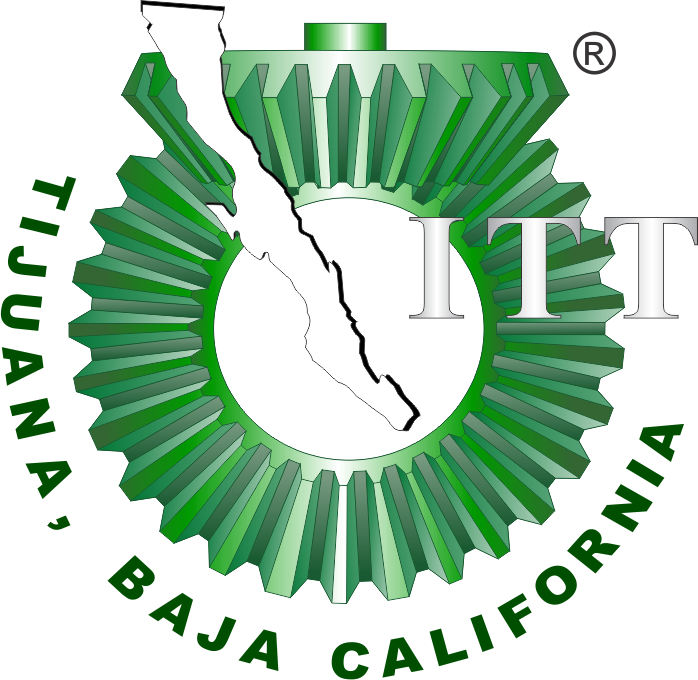

# Práctica 5.10: Regeneración de glóbulos rojos 

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

Nombre del alumno: Maria Belen Galindo Ramirez                                                                 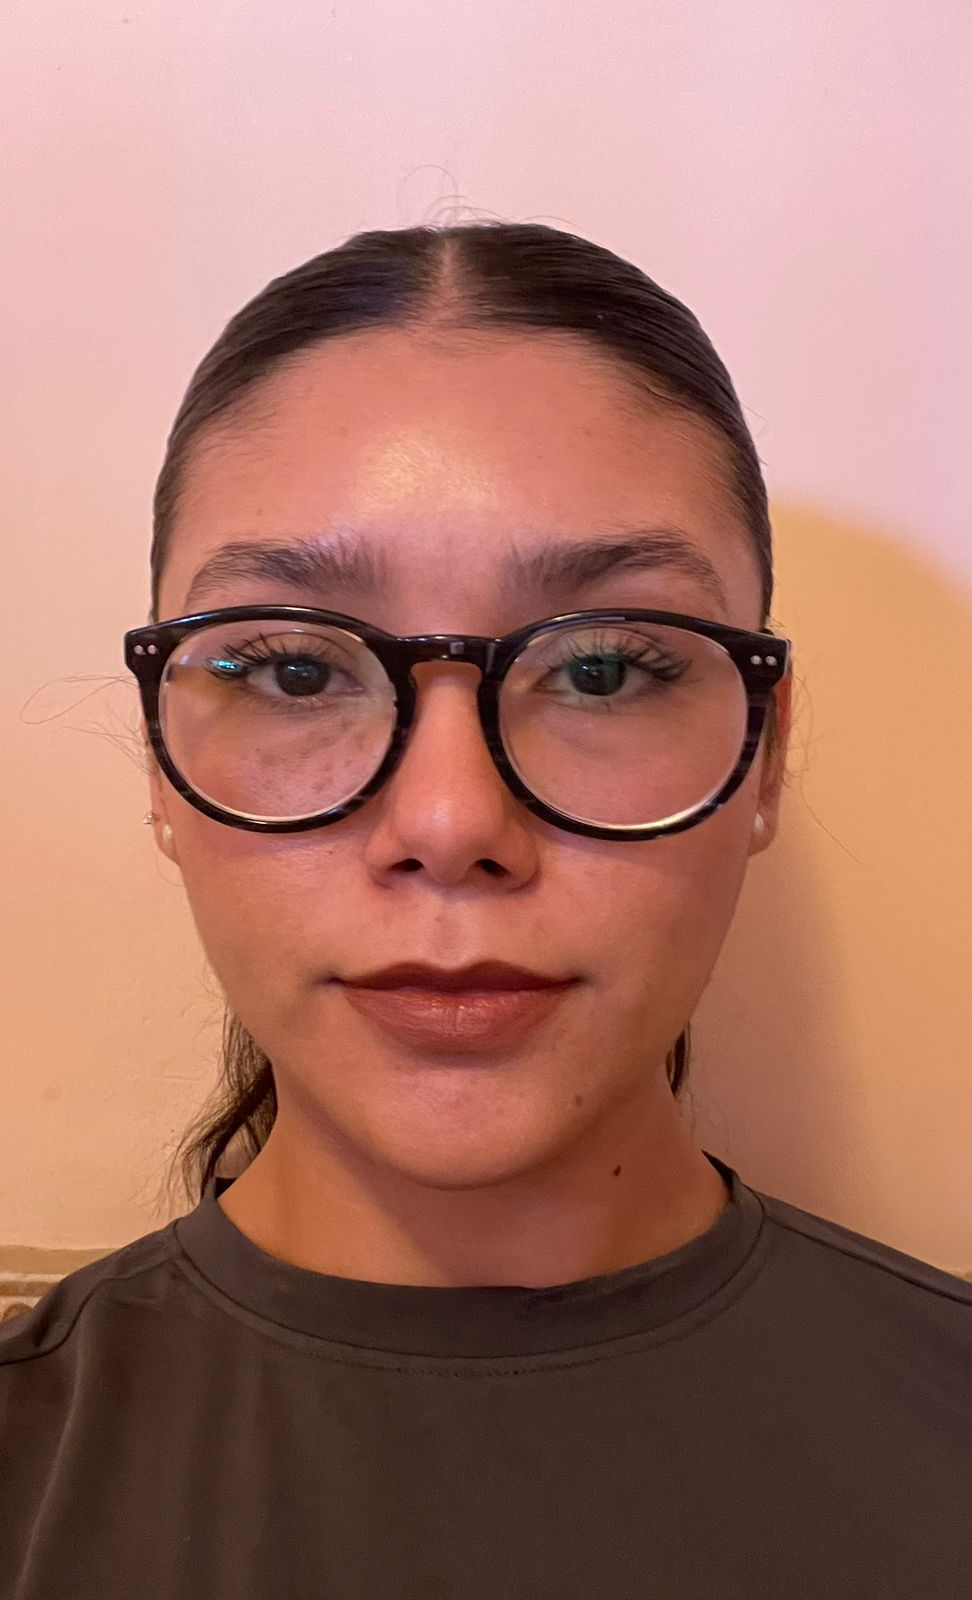

Número de control: 22211755

Correo institucional: l22211755**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend = 180; %Tiempo de la simulacion en dias 
dt = 1E-3; %Intervalo de integracion para el metodo de solucion por diferencias finitas
n = round(tend/dt); %Cantidad de iteraciones para el metodo numerico 

%Condiciones iniciales base para cada paciente 
x1_0 = 59; x2_0 = 44; x3_0 = 885;

%Parametros particulares para cada paciente
gamma = [0.769; 0.388; 0.510; 0.590; 0.262; 0.324; 0.356; 0.089; 0.243; 0.057];
beta = [1.650; 0.867; 1.617; 2.615; 1.518; 2.676; 0.891; 2.557; 0.925; 0.879];

seed = 22211755; %Semilla para asegurar reproducibilidad 
rng(seed, 'twister')
%Intervalo de las condiciones iniciales 
xmin = 0.99; xmax = 1.01;
interval = xmin + (xmax - xmin).*rand(numel(gamma),1);

%Condiciones iniciales para cada paciente 
x1_0 = x1_0*interval; disp('x1(0) = 0'); disp(x1_0');...
x2_0 = x2_0*interval; disp('x2(0) = 0'); disp(x2_0');... 
x3_0 = x3_0*interval; disp('x3(0) = 0'); disp(x3_0');

x1(0) = 0
   59.3506   58.6645   59.5039   58.5365   59.5025   58.4678   59.5135   59.1080   58.4406   58.7068



x2(0) = 0
   44.2614   43.7498   44.3758   43.6543   44.3747   43.6031   44.3830   44.0805   43.5828   43.7814



x3(0) = 0
  890.2583  879.9681  892.5584  878.0474  892.5376  877.0174  892.7030  886.6200  876.6085  880.6022



## Caso: Sin transfusión sanguínea [u(t) = 0]

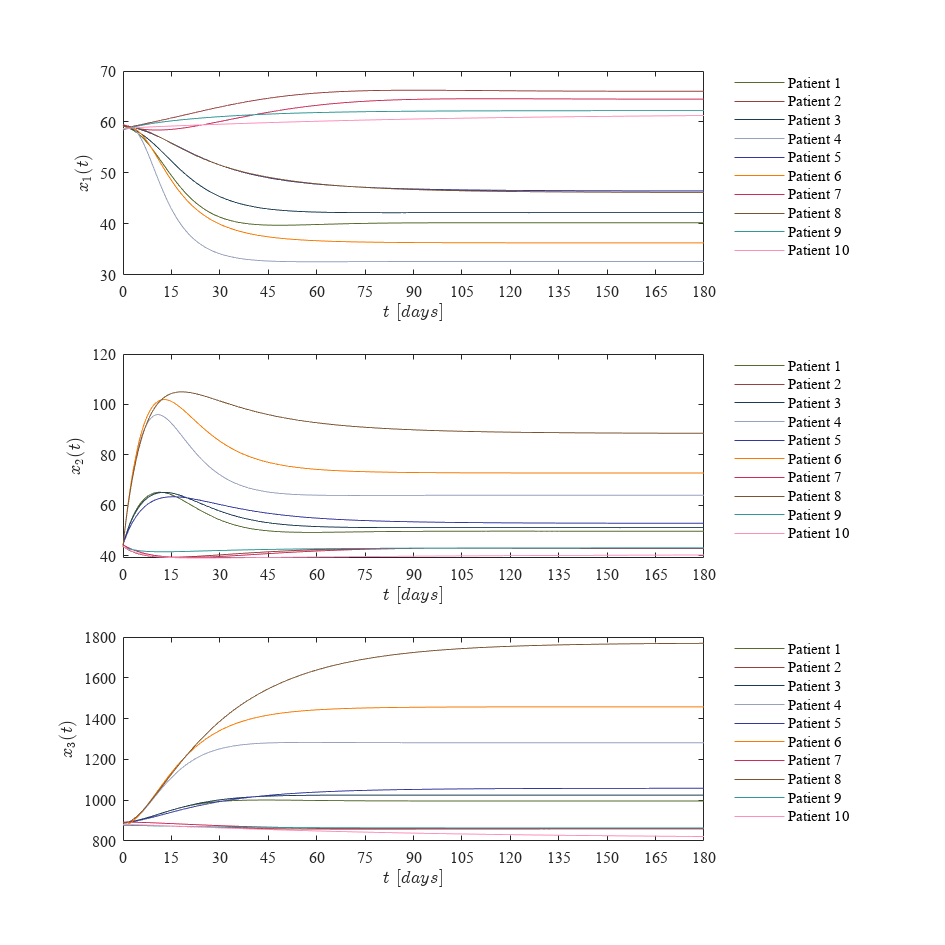

u = zeros(n+1,1); %No hay transfusion 
fig = 1;
for i = 1:10
[t,x1,x2,x3] = system(x1_0(i),x2_0(i),x3_0(i),beta(i),gamma(i),u,dt,tend);
plotdata(t,x1,x2,x3,fig)
end 

## Caso: transfusión sanguínea

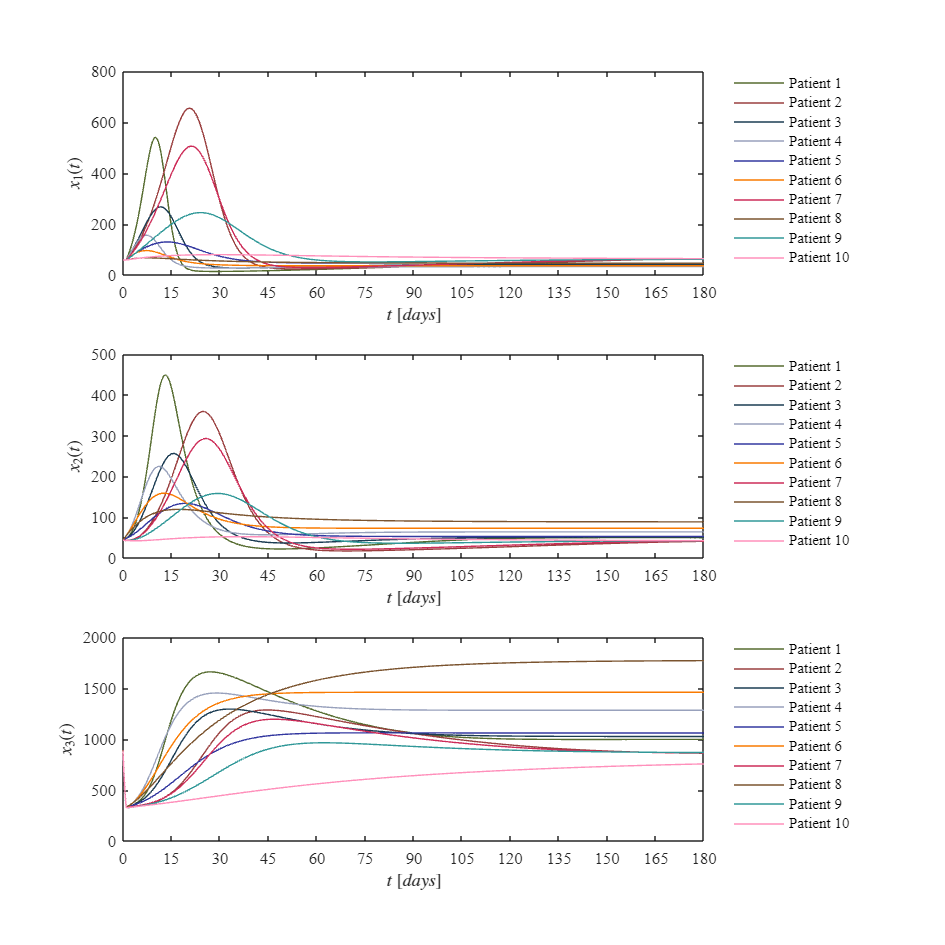

close all;
u(1:1/dt) = 1; %???
fig = 2;
for i = 1:10
[t,x1,x2,x3] = system(x1_0(i),x2_0(i),x3_0(i),beta(i),gamma(i),u,dt,tend);
plotdata(t,x1,x2,x3,fig)
end 

## Función: Modelo matemático 


$$ $$

$$\dot{x_1 } =\beta \left(X_0 -k_1 x_1 \right)+\frac{\gamma \left(B_{\textrm{ase}} -x_3 \right)\left(1-u\left(t\right)\right)x_1 }{B_{\textrm{ase}} }$$



$$\dot{x_2 } =\beta \left(k_1 x_1 -k_2 x_2 \right)$$



$$\dot{x_3 } =\beta \left(k_2 x_2 -ax_3 \right)-u\left(t\right)x_3$$


function [t,x1,x2,x3] = system(x1_0,x2_0,x3_0,beta,gamma,u,dt,tend)
    %Parametros fijos del sistema
    Base = 885.42; x0 = 7.3785; k1 = 0.125; k2 = 0.1667; alpha = 0.00833;
    t = (0:dt:tend)';
    n = round(tend/dt);
    x1 = zeros(n+1,1);x1(1) = x1_0;
    x2 = zeros(n+1,1);x2(1) = x2_0;
    x3 = zeros(n+1,1);x3(1) = x3_0;

    for i = 1:n %Metodo de Euler (diferencias finitas)
        x1(i+1) = x1(i) + (beta*(x0 - k1*x1(i)) + gamma*(Base - x3(i))*(1 -u(i))*x1(i)/Base)*dt;
        x2(i+1) = x2(i) + (beta*k1*x1(i) - k2*x2(i))*dt;
        x3(i+1) = x3(i) + (beta*(k2*x2(i) - alpha*x3(i)) - u(i)*x3(i))*dt;
    end 
end 

## Función: Soluciones en el tiempo 

function plotdata(t,x1,x2,x3,fig)
    set(figure(fig),'Color', 'w')
    set(gcf,'Units','Centimeters','Position',[1,1,20,20])
        mycolors = [85, 107, 47;
            154, 63, 63;
            27, 60, 83;
            152, 161, 188;
            51, 56, 160;
            249, 122, 0;
            205, 44, 88;
            123, 84, 47;
            48, 152, 152;
            255, 144, 187;
]/255;


    subplot(3,1,1)
    hold on; grid off; box on;colororder(mycolors)
    plot(t,x1)
    xlabel('$t$ $[days]$','Interpreter','latex','FontSize',10)
    ylabel('$x_1(t)$','Interpreter','latex','FontSize',10)
    xlim([0 180]); xticks(0:15:180)
    set(gca,'FontName','Times New Roman','FontSize',10)
    L = legend('Patient 1','Patient 2','Patient 3','Patient 4','Patient 5',...
        'Patient 6','Patient 7','Patient 8','Patient 9','Patient 10');
    set(L,'FontSize',9,'Box','Off','Location','NorthEastOutside');

    subplot(3,1,2)
    hold on; grid off; box on; colororder(mycolors)
    plot(t,x2)
    xlabel('$t$ $[days]$','Interpreter','latex','FontSize',10)
    ylabel('$x_2(t)$','Interpreter','latex','FontSize',10)
    xlim([0 180]); xticks(0:15:180)
    set(gca,'FontName','Times New Roman','FontSize',10)
    L = legend('Patient 1','Patient 2','Patient 3','Patient 4','Patient 5',...
        'Patient 6','Patient 7','Patient 8','Patient 9','Patient 10');
    set(L,'FontSize',9,'Box','Off','Location','NorthEastOutside');

    subplot(3,1,3)
    hold on; grid off; box on; colororder(mycolors)
    plot(t,x3)
    xlabel('$t$ $[days]$','Interpreter','latex','FontSize',10)
    ylabel('$x_3(t)$','Interpreter','latex','FontSize',10)
    xlim([0 180]); xticks(0:15:180)
    set(gca,'FontName','Times New Roman','FontSize',10)
    L = legend('Patient 1','Patient 2','Patient 3','Patient 4','Patient 5',...
        'Patient 6','Patient 7','Patient 8','Patient 9','Patient 10');
    set(L,'FontSize',9,'Box','Off','Location','NorthEastOutside');

    if fig == 1
        exportgraphics(gcf,'Caso sin transfusion.pdf','ContentType','vector')
         exportgraphics(gcf,'Caso sin transfusion.png','ContentType','vector')
    elseif fig == 2 
        exportgraphics(gcf,'Caso con transfusion.pdf','ContentType','vector')
         exportgraphics(gcf,'Caso con transfusion.png','ContentType','vector')
    end 
end 

   